Vytvoření melspektrogramů + uložení obrázků

clear

folder='C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\projekt-matlab\esc\004 - Baby cry';
subfolder = 'C:\Users\hrusk\Desktop\VŠ\5-semestr\ZOD\projekt-matlab\esc-img\004 - Baby cry';
audio_files = dir(fullfile(folder,'*.ogg'));

for i = 1:numel(audio_files)
    filename=audio_files(i).name;
    [data,Fs] = audioread(fullfile(folder,filename));
    AudioData{i}=data(:,1);
    f = figure;
    melSpectrogram(AudioData{i}, Fs);
    set(gca, 'Visible', 'off');
    colorbar('off');
    audio_files(i).name = audio_files(i).name(1:end-4);
    saveas(f, fullfile(subfolder, audio_files(i).name + ".png"));
end

Vytvoření obazového datasetu

clear
imageDatasetPath = fullfile('esc-img');
imds = imageDatastore(imageDatasetPath, 'IncludeSubfolders', true, 'LabelSource','foldernames');

Rozdělení datasetu

[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');

Nastavení CNN

I = imread('esc-img\001 - Dog bark\1-30226-A.png');
imagesize = size(I);

numClasses = countEachLabel(imdsTrain);

Unrecognized function or variable 'imdsTrain'.

numClasses = height(numClasses);

layers = [
    imageInputLayer(imagesize)

    convolution2dLayer(3,12,'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,2*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding',"same")
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,4*12,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([1 13])

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs',100, ...
    'Shuffle',"every-epoch",...
    "Plots",'training-progress',...
    "Verbose",false,...
    'ValidationData',imdsValidation,...
    'ExecutionEnvironment','cpu');

Trénování CNN

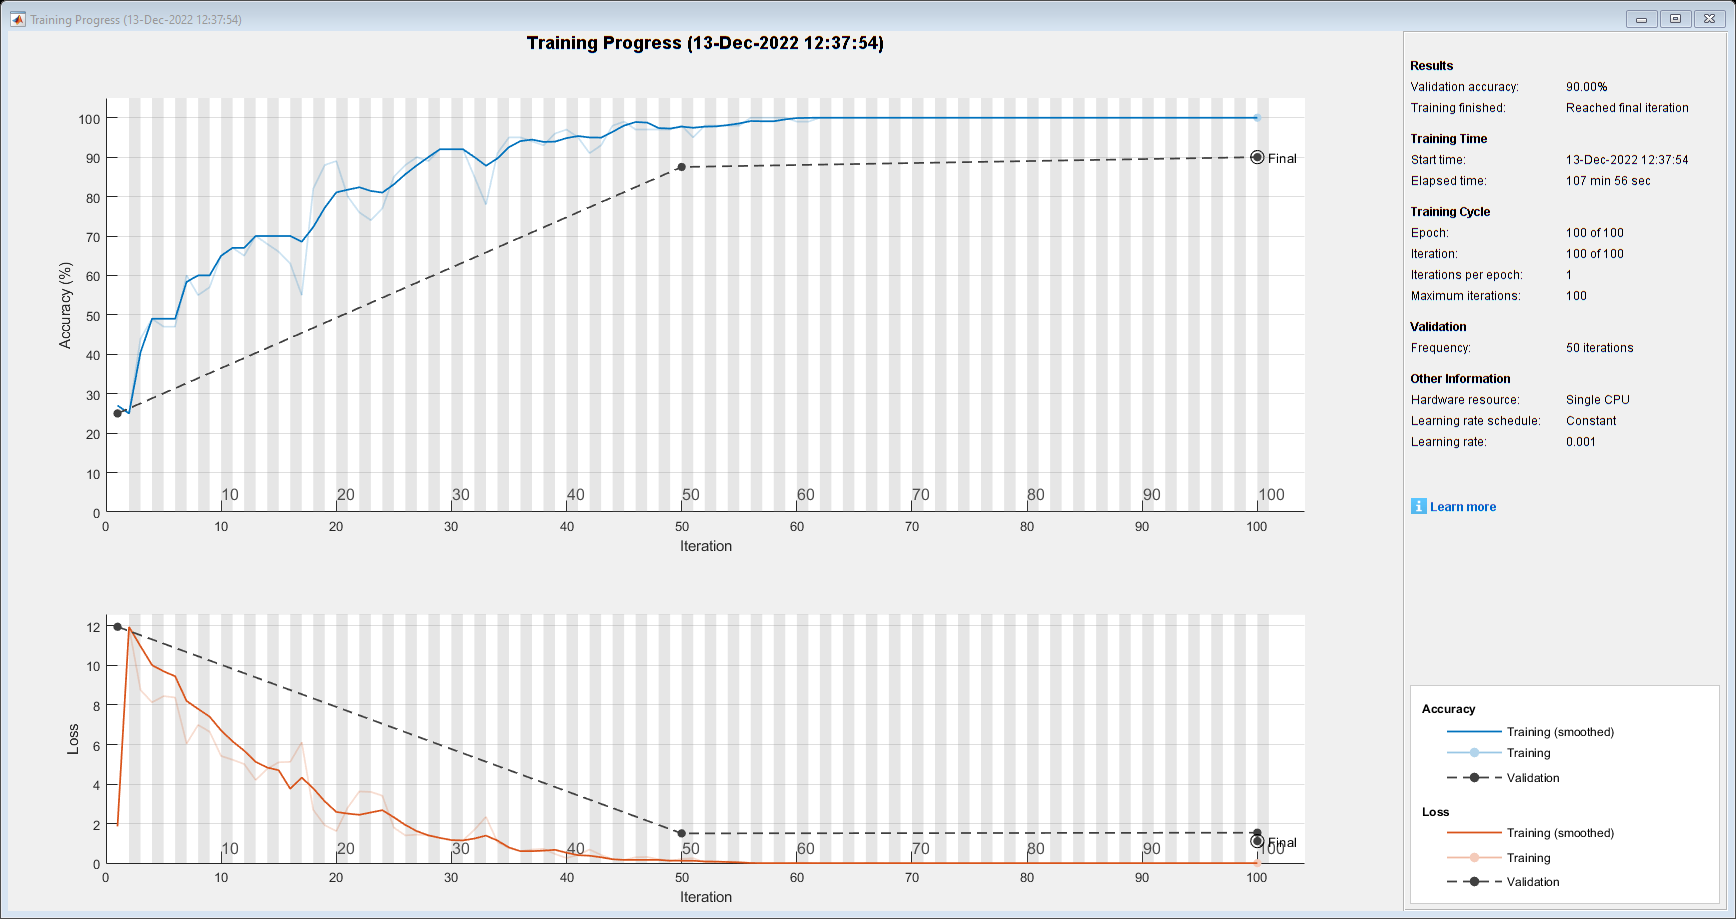

% net = trainNetwork(imdsTrain, layers, options);

save net;

Přesnost neuronky

Pred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracyNet = sum(Pred == YValidation)/numel(YValidation)

accuracy = 0.9000

load net;

Testování

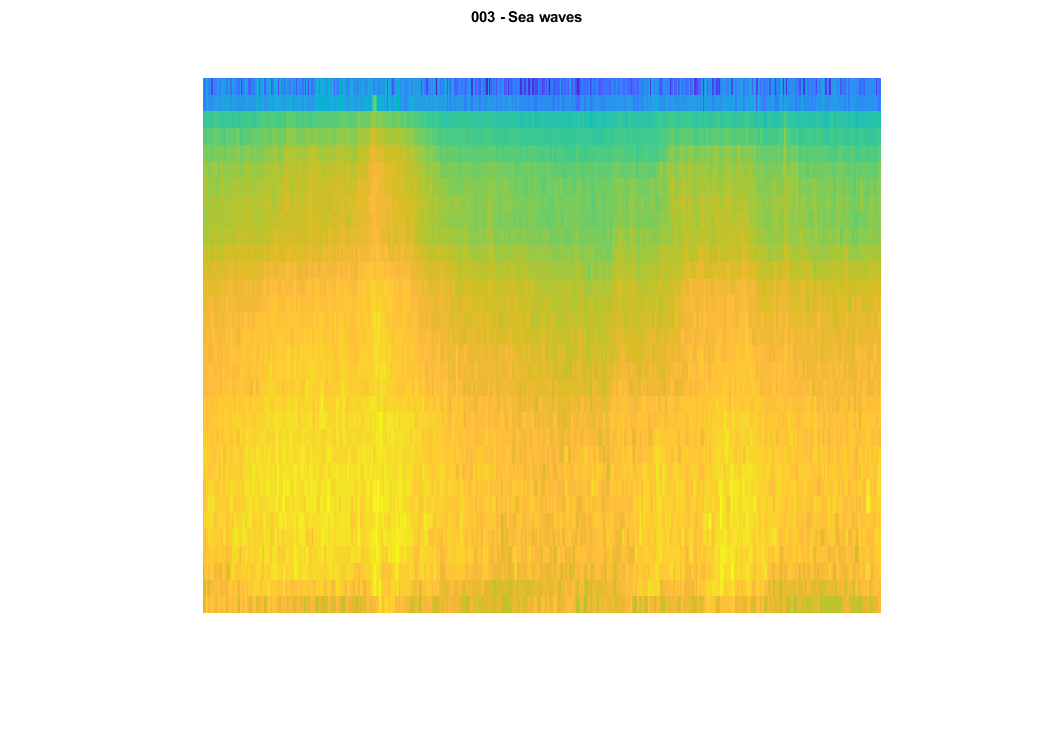

[baseFileName, folder] = uigetfile('*.png');
fullFileName = fullfile(folder, baseFileName);
theImage = imread(fullFileName);
label = classify(net, theImage);

imshow(theImage)
title(label)

Načtení (předtrénované) resNet50

resNet = resnet50;

Nastavení resNet50 - obměna fullyConnected a classification Layerů

inputSize = resNet.Layers(1).InputSize;

lgraph = layerGraph(resNet);

classifLayer = resNet.Layers(end);

classifLayer =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_fc1000'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


connectedLayer = resNet.Layers(end-2);

connectedLayer =   FullyConnectedLayer with properties:

          Name: 'fc1000'

   Hyperparameters
     InputSize: 2048
    OutputSize: 1000

   Learnable Parameters
       Weights: [1000×2048 single]
          Bias: [1000×1 single]

  Show all properties



newLearnableLayer = fullyConnectedLayer(numClasses, "Name", "new_connectedLayer");
lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);

newClassLayer = classificationLayer("Name", "new_classifLayer");
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

Kontrola nastavení resNet50

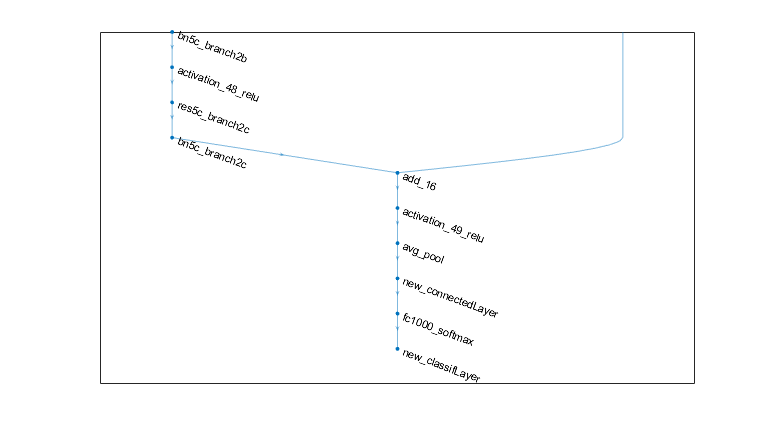

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

Trénování resNet50 (augmentace vstupních dat)

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Nastavení restNet50

valFrequency = floor(numel(augimdsTrain.Files)/10);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

Trénování ResNet50

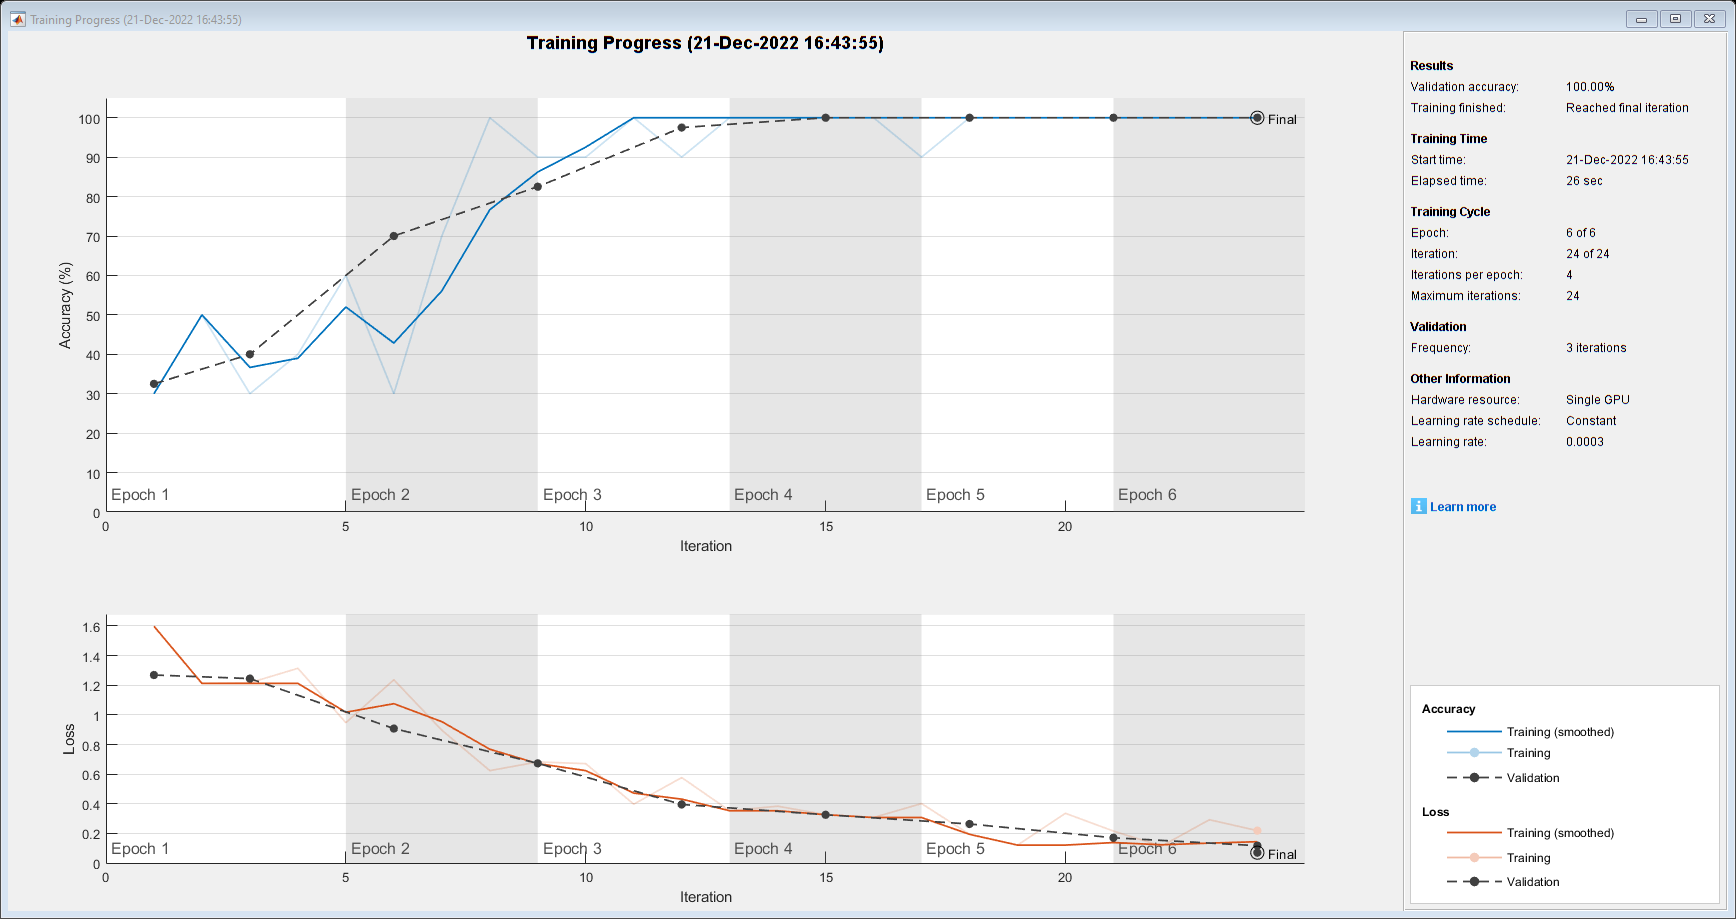

resNet = trainNetwork(augimdsValidation,lgraph,options);

Přesnost resNet50

[YPred,probs] = classify(resNet,augimdsValidation);
accuracyRes = mean(YPred == imdsValidation.Labels)

accuracyRes = 1

Testování resNet50

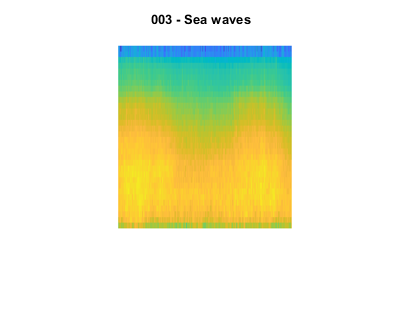

inputSize = resNet.Layers(1).InputSize;
rows = inputSize(1);
cols = inputSize(2);

[baseFileName, folder] = uigetfile('*.png');
fullFileName = fullfile(folder, baseFileName);
theImage = imread(fullFileName);
theImage = imresize(theImage, [rows cols]);

label = classify(resNet, theImage);

imshow(theImage)
title(label)